# Fourier series

f = @(x) exp( sin(3*x) - 3*cos(2*x) );
clf, fplot(f,[-pi pi],'k','linew',2)

u = @(k,x) exp(1i*k*x)/sqrt(2*pi);
c0 = integral(@(x) conj(u(0,x)).*f(x),-pi,pi);
for k = 1:20
    cplus(k) = integral(@(x) conj(u(k,x)).*f(x),-pi,pi);
    cminus(k) = integral(@(x) conj(u(-k,x)).*f(x),-pi,pi);
end

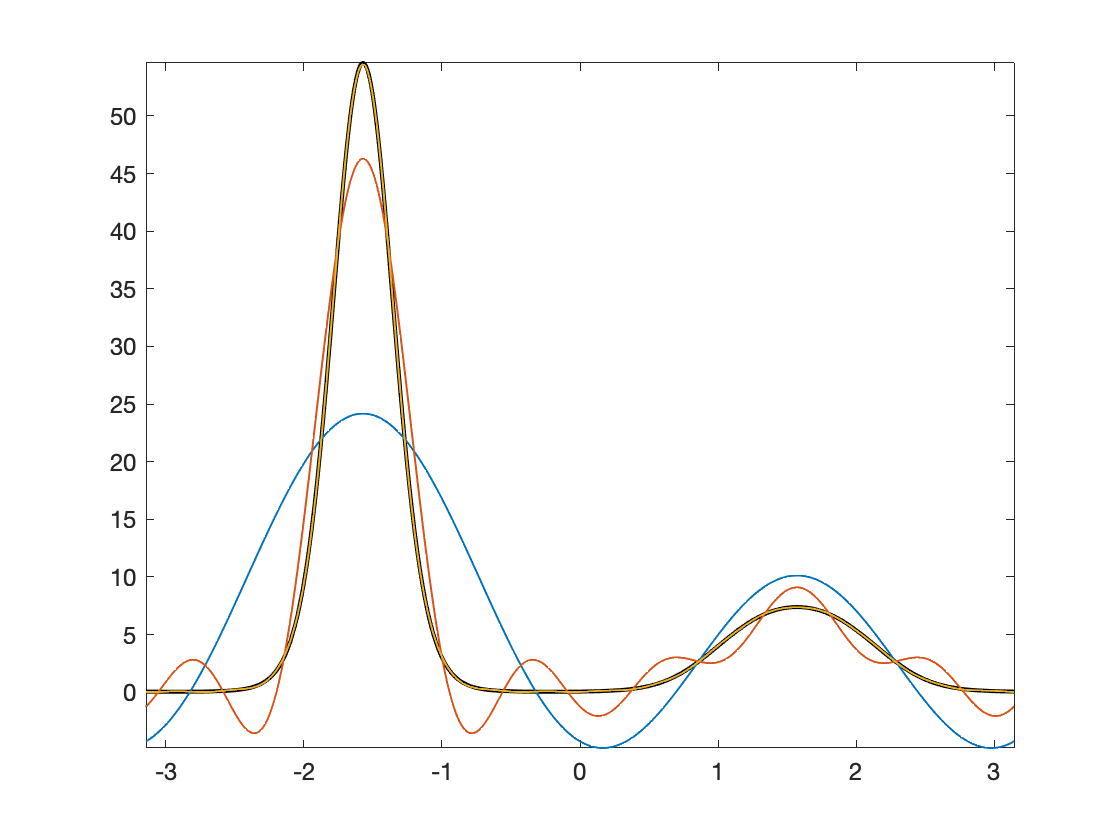

x = linspace(-pi,pi,400);
s = c0/sqrt(2*pi);
for k = 1:2
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)
for k = 3:6
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)
for k = 7:15
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)

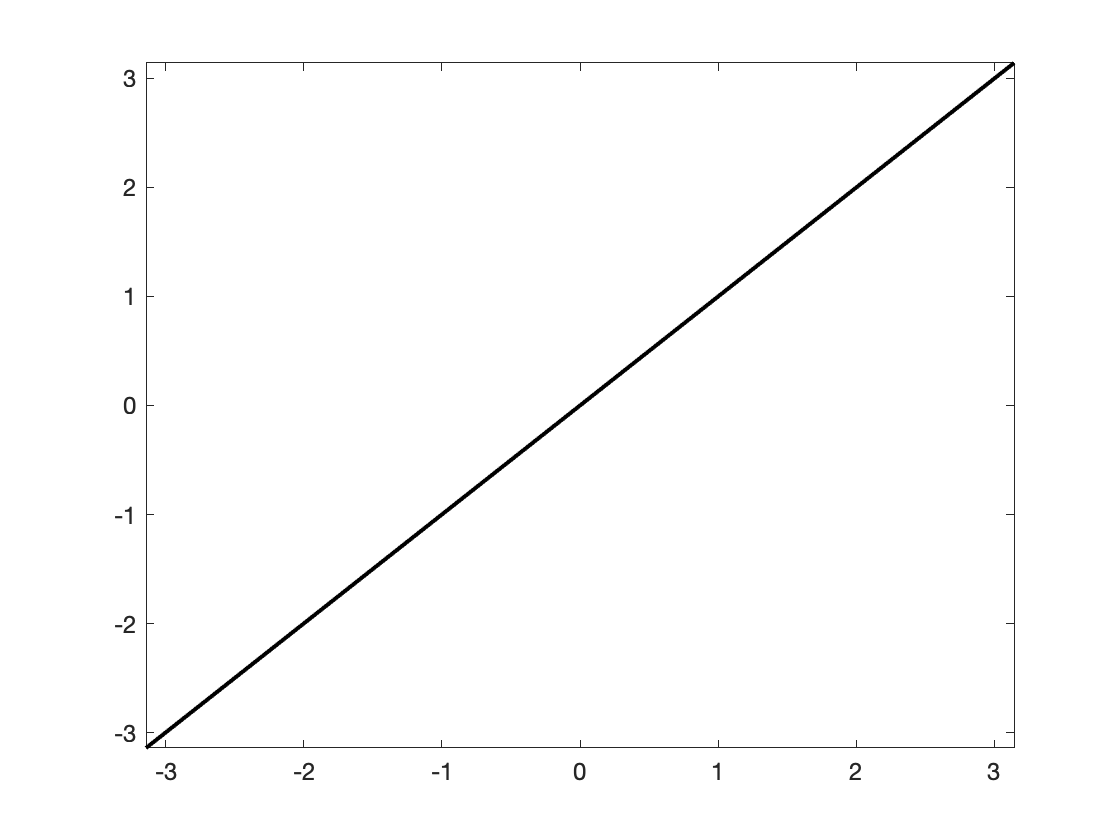

f = @(x) x;
clf, fplot(f,[-pi pi],'k','linew',2)

u = @(k,x) exp(1i*k*x)/sqrt(2*pi);
c0 = integral(@(x) conj(u(0,x)).*f(x),-pi,pi);
for k = 1:20
    cplus(k) = integral(@(x) conj(u(k,x)).*f(x),-pi,pi);
    cminus(k) = integral(@(x) conj(u(-k,x)).*f(x),-pi,pi);
end

ans =    0.0000 - 2.5066i   0.0000 + 1.2533i  -0.0000 - 0.8355i   0.0000 + 0.6267i  -0.0000 - 0.5013i   0.0000 + 0.4178i  -0.0000 - 0.3581i  -0.0000 + 0.3133i   0.0000 - 0.2785i  -0.0000 + 0.2507i   0.0000 - 0.2279i   0.0000 + 0.2089i  -0.0000 - 0.1928i   0.0000 + 0.1790i  -0.0000 - 0.1671i   0.0000 + 0.1567i   0.0000 - 0.1474i  -0.0000 + 0.1393i  -0.0000 - 0.1319i   0.0000 + 0.1253i   0.0000 + 2.5066i   0.0000 - 1.2533i  -0.0000 + 0.8355i   0.0000 - 0.6267i  -0.0000 + 0.5013i   0.0000 - 0.4178i  -0.0000 + 0.3581i  -0.0000 - 0.3133i   0.0000 + 0.2785i  -0.0000 - 0.2507i   0.0000 + 0.2279i   0.0000 - 0.2089i  -0.0000 + 0.1928i   0.0000 - 0.1790i  -0.0000 + 0.1671i   0.0000 - 0.1567i   0.0000 + 0.1474i  -0.0000 - 0.1393i  -0.0000 + 0.1319i   0.0000 - 0.1253i


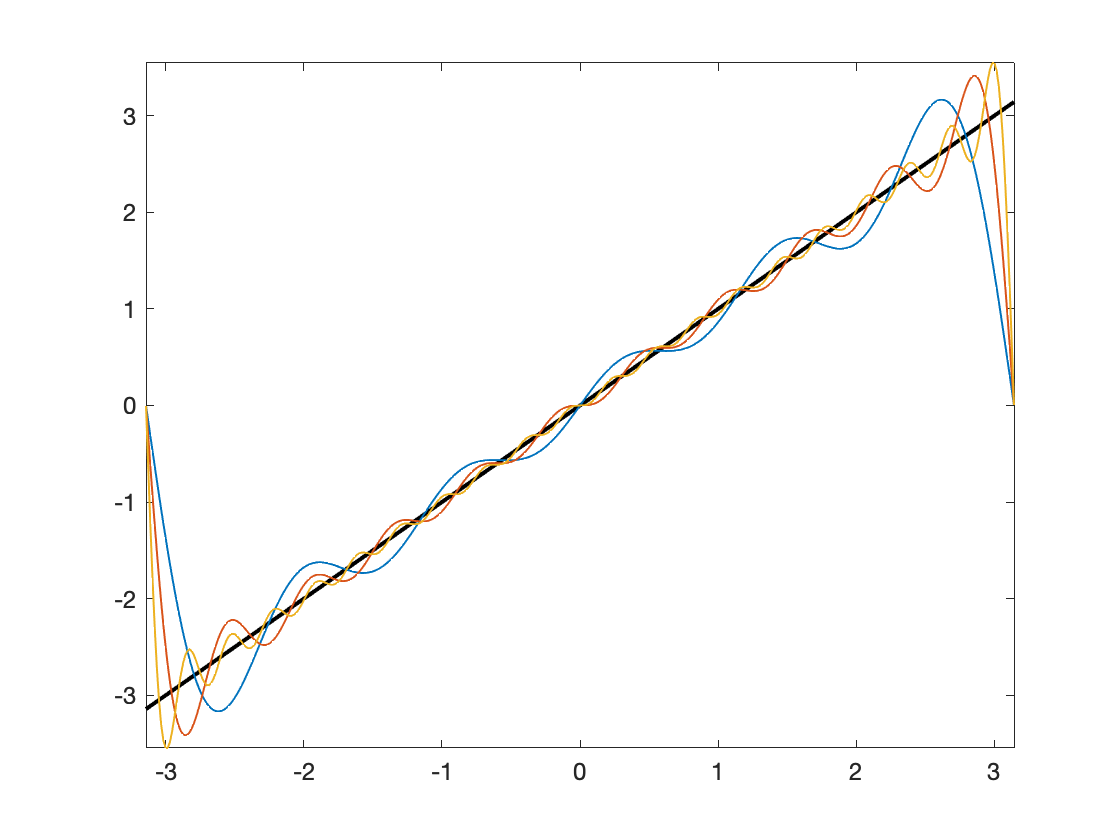

x = linspace(-pi,pi,400);
s = c0/sqrt(2*pi);
for k = 1:5
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)
for k = 6:10
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)
for k = 11:20
    s = s + cplus(k)*u(k,x) + cminus(k)*u(-k,x);
end
hold on, plot(x,s)